**Project - Image Processing (Moon and Jupiter)**

**Sneh Shah                         11-02-2024**

**Image Properties**

image = imread("E:\PHOTOS\pipp_20240316_210839\_MG_0057\00__MG_0057.tif") ; %imshow(f) ;

info = imfinfo("E:\PHOTOS\pipp_20240316_210839\_MG_0057\00__MG_0057.tif") ; disp(info) ;

                     Filename: 'E:\PHOTOS\pipp_20240316_210839\_MG_0057\00__MG_0057.tif'
                  FileModDate: '16-Mar-2024 21:10:28'
                     FileSize: 108149756
                       Format: 'tif'
                FormatVersion: []
                        Width: 5202
                       Height: 3465
                     BitDepth: 48
                    ColorType: 'truecolor'
              FormatSignature: [73 73 42 0]
                    ByteOrder: 'little-endian'
               NewSubFileType: 0
                BitsPerSample: [16 16 16]
                  Compression: 'Uncompressed'
    PhotometricInterpretation: 'RGB'
                 StripOffsets: 176
              SamplesPerPixel: 3
                 RowsPerStrip: 3465
              StripByteCounts: 108149580
                  XResolution: 72
                  YResolution: 72
               ResolutionUnit: 'Inch'
                     Colormap: []
          PlanarConfiguration: 'Chunky'
                    Ti

**Read and Write **

image = imread("E:\PHOTOS\pipp_20240316_210839\_MG_0057\00__MG_0057.tif") ; %imshow(f) ;
imwrite(image,"E:\PHOTOS\pipp_20240316_210839\_MG_0057\NewIm.png",'png') ;

**Changing Color Space**

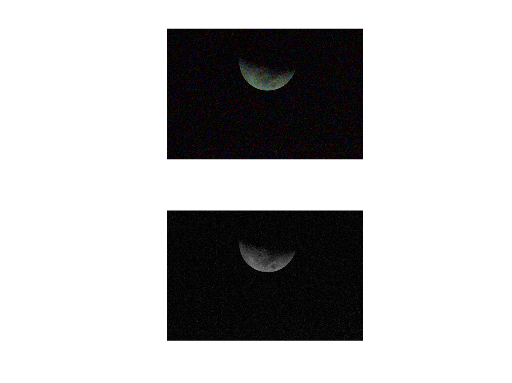

image = imread("E:\PHOTOS\pipp_20240316_210839\_MG_0057\00__MG_0057.tif") ; %imshow(f) ;
gray_image = rgb2gray(image) ;
subplot(2,1,1) ; imshow(image) ; subplot(2,1,2) ; imshow(gray_image) ;

**Splitting Channels**

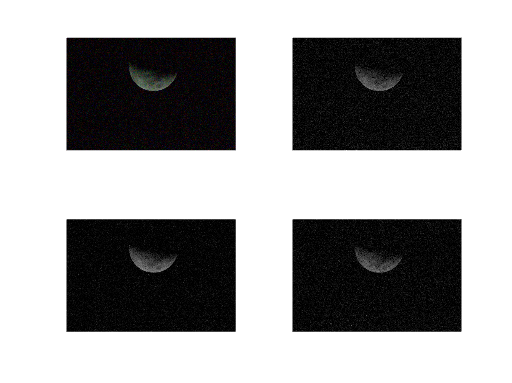

image = imread("E:\PHOTOS\pipp_20240316_210839\_MG_0057\00__MG_0057.tif") ; %imshow(f) ;
red_channel = image(:,:,1) ; green_channel = image(:,:,2) ; blue_channel = image(:,:,3) ;

subplot(2,2,1) ; imshow(image) ; subplot(2,2,2) ; imshow(red_channel) ; subplot(2,2,3) ; imshow(green_channel) ; subplot(2,2,4) ; imshow(blue_channel) ;

**Accessing Pixel Value of an RGB Image**

image = imread("E:\PHOTOS\pipp_20240316_210839\_MG_0057\00__MG_0057.tif") ; %imshow(f) ;
red_channel = image(50,70,1) ; green_channel = image(50,70,2) ; blue_channel = image(50,70,3) ;
fprintf('Value of red , green and blue pixel is %d , %d , %d ',red_channel,green_channel,blue_channel) ;

Value of red , green and blue pixel is 4248 , 773 , 3371 

**Repeated Convolution of a 1D Signal**

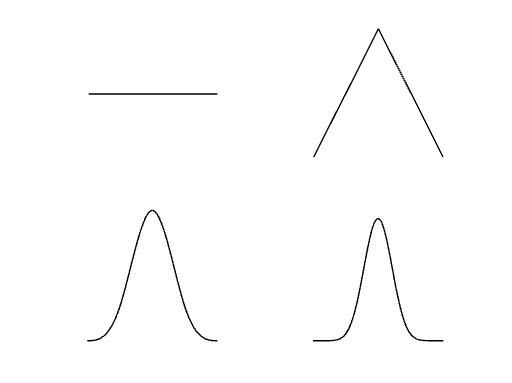

s1 = ones(64,1) ; n_s1 = s1./sum(s1) ; %normalizing 

c1 = conv(n_s1,n_s1) ; n_c1 = c1./sum(c1) ;
c2 = conv(n_c1,n_c1) ; n_c2 = c2./sum(c2) ;
c3 = conv(n_c2,n_c2) ; n_c3 = c3./sum(c3) ;

subplot(2,2,1) ; plot(s1,'k-') ; axis square ; axis off ;
subplot(2,2,2) ; plot(n_c1,'k-') ; axis square ; axis off ;
subplot(2,2,3) ; plot(n_c2,'k-') ; axis square ; axis off ;
subplot(2,2,4) ; plot(n_c3,'k-') ; axis square ; axis off ;


%1D Signal approaches normal distribution

**Convolution of a 2D Image**

What is a convolution kernel?

In image processing, a kernel, convolution matrix, or mask is a small matrix used for blurring, sharpening, embossing, edge detection, and more. 

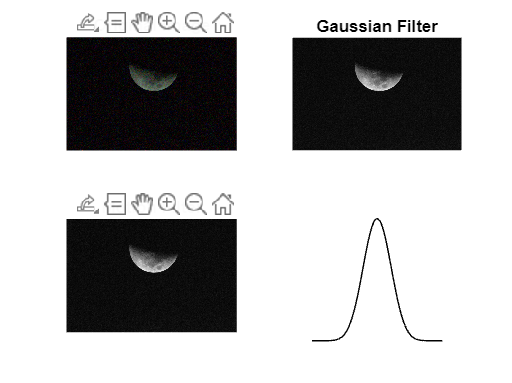

image = imread("E:\PHOTOS\pipp_20240316_210839\_MG_0057\00__MG_0057.tif") ; %imshow(f) ;
gray_image = rgb2gray(image) ; gray_image = double(gray_image) ; %Bcoz filter that is used needs double data type

%Kernel
PSF = fspecial('gaussian' , [5 5] , 2) ; 
motion_filter = fspecial('motion' , 10 , 45) ;

convolutiongf = conv2(PSF,gray_image) ; 
convolutionmf = imfilter(gray_image , motion_filter,'replicate') ;
%selfconv = conv2(gray_image,gray_image) ; %Takes a lot of time , never ends 

subplot(2,2,1) ; imshow(image) ; title("Original Image") ;
subplot(2,2,2) ; imshow(convolutiongf , []) ; title("Gaussian Filter") ;
subplot(2,2,3) ; imshow(convolutionmf , []) ; title("Motion Filter") ;

%subplot(2,2,4) ; imshow(selfconv , []) ; title("Self Convolution") ;